# Saé13: Activité 1

clear all
close all

Charger le fichier audio « verlan »sur Matlab:

[y,Fs] = audioread('verlan.m4a');

% Normalisation du signal audio (avoir un son correcte).
y = y / max(abs(y));

Jouer le signal audio grâce à Matlab:

%Jouer l'audio original.
sound(y,Fs);
pause(length(y) / Fs);

Visualiser sur Matlab le signal audio:

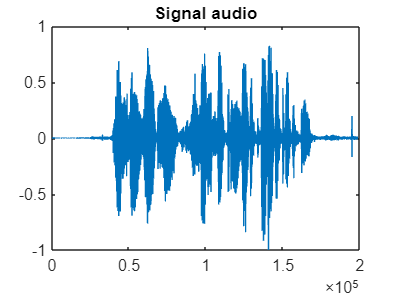

plot(y);
title('Signal audio');

Décomposition des syllabes:

% Définir manuellement les indices de début et de fin de syllabes
indices_debut = [35800, 48000, 59000, 68000, 82000, 93000, 98000, 102000,106000, 115000, 120000, 131000, 140000, 150000, 155000,];
indices_fin = [48000, 59000, 69000, 82000, 93000, 98000, 102000, 106000,115000, 120000, 131000, 140000, 150000, 155000, 169000,];

% Diviser le signal en syllabes
syllabes = cell(1, length(indices_debut));
for i = 1:length(indices_debut)
    syllabes{i} = y(indices_debut(i):indices_fin(i));
end

%sound(syllabes{10}, Fs);


Visualisation des différentes syllabes du signal sonore « verlan »,

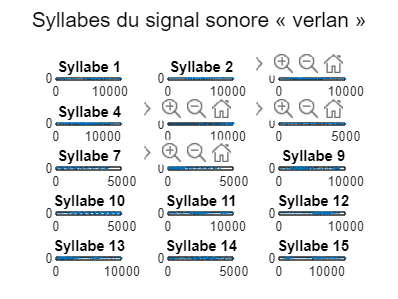

figure;
sgtitle('Syllabes du signal sonore « verlan »');
for i = 1:15
    subplot(5, 3, i);
    plot(syllabes{i});
    title(['Syllabe ' num2str(i)]);
end

Séparation du signal « verlan »pour obtenir le signal « non verlan »:

% Mot 1(en verlan):

%vasy = cat(1, syllabes{2}, syllabes{1}), Fs;
%sound(vasy, Fs);
%pause(length(vasy) / Fs);


% Mot 2(en verlan):

%merci = cat(1, syllabes{4}, syllabes{3}), Fs;
%sound(merci, Fs);
%pause(length(merci) / Fs);

% Mot 3 et 4:

%maislaisse = cat(1, syllabes{5:8}), Fs;
%sound(maislaisse, Fs);
%pause(length(maislaisse) / Fs);

% Mot 5:(celui-ci et en verlan car il y a déja 3 mots transformés)

%bertom = cat(1, syllabes{10}, syllabes{9}), Fs;
%sound(bertom, Fs);
%pause(length(bertom) / Fs);

% Mot 6 et 7:

%cestquoice = cat(1,syllabes{11:13}), Fs;
%sound(cestquoice, Fs);
%pause(length(cestquoice) / Fs);

% Mot 8(en verlan):

%truc = cat(1, syllabes{15}, syllabes{14}), Fs;
%sound(truc, Fs);
%pause(length(truc) / Fs);

Visualisation des différentes syllabes du signal sonore « non verlan »

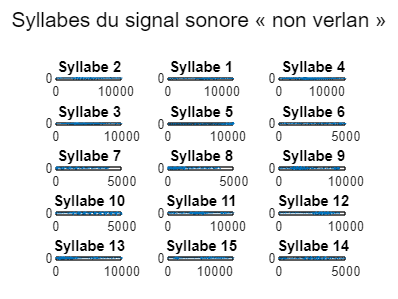

% Ordonner les syllabes du signal sonore « non verlan »
sequence_nonverlan = [2, 1, 4, 3, 5:8, 9, 10, 11:13, 15, 14];
syllabes_nonverlan = syllabes(sequence_nonverlan);

% Afficher les syllabes dans l'ordre « non verlan »
figure;
sgtitle('Syllabes du signal sonore « non verlan »');
for i = 1:length(sequence_nonverlan)
    subplot(5, 3, i);
    plot(syllabes_nonverlan{i});
    title(['Syllabe ' num2str(sequence_nonverlan(i))]);
end

Jouer le signal audio « non verlan », 

% Jouer les syllabes dans l'ordre « non verlan »
sound(cat(1, syllabes_nonverlan{:}), Fs);

Sauvegarde du signal « non verlan »dans un fichier du même type(format wav car m4a non prit en charge) que le signal « verlan »

% Définir l'audio « non verlan » à sauvegarder
non_verlan = cat(1, syllabes_nonverlan{:});

% Enregistrer la séquence audio dans un nouveau fichier
output_filename = 'C:\Users\lolo5\Desktop\BUT1 RT\S1\Sae13/non_verlan.wav';
audiowrite(output_filename, non_verlan, Fs);
